# Discrete Time PID controller implementation to the continuous time plant

## S and Z domain units

s = tf("s");
z = tf("z");

## Transfer function of the plant

Gs = tf(-m*g*d, [L*(J/R^2+m) 0 0])

Gs =
 
  -0.03237
  ---------
  0.154 s^2
 
Continuous-time transfer function.



## Sampling time

Ts = 0.1;

## Z Domain PID Parameters

P = -19.876

P = -19.8760

I = -4.44

I = -4.4400

D = -22.24

D = -22.2400

## Z Domain PID Controller

PID_z = P+I*Ts/(z-1)+D/Ts*(z-1)/z

PID_z =
 
  -242.3 z^2 + 464.2 z - 222.4
  ----------------------------
            z^2 - z
 
Sample time: unspecified
Discrete-time transfer function.



PID_z.Ts = Ts

PID_z =
 
  -242.3 z^2 + 464.2 z - 222.4
  ----------------------------
            z^2 - z
 
Sample time: 0.1 seconds
Discrete-time transfer function.



## Open loop transfer function of the PID controlled system

Gzas = d2c(PID_z, "tustin") * Gs

Gzas =
 
  15.04 s^2 + 12.87 s + 2.875
  ---------------------------
     0.154 s^4 + 3.08 s^3
 
Continuous-time transfer function.



## Closed loop transfer function of the PID controlled system

Ts = feedback(Gzas, 1)

Ts =
 
             15.04 s^2 + 12.87 s + 2.875
  --------------------------------------------------
  0.154 s^4 + 3.08 s^3 + 15.04 s^2 + 12.87 s + 2.875
 
Continuous-time transfer function.



## Step response of the CL

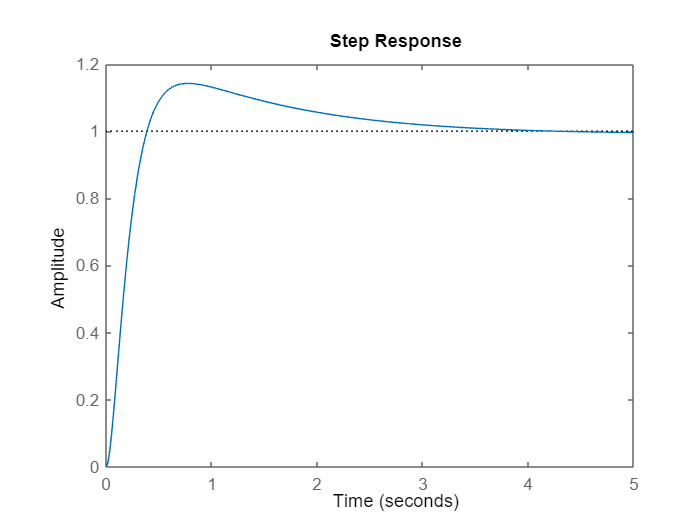

step(Ts)

stepinfo(Ts)

ans = struct with fields:
         RiseTime: 0.2636
    TransientTime: 2.9499
     SettlingTime: 2.9499
      SettlingMin: 0.9053
      SettlingMax: 1.1422
        Overshoot: 14.2220
       Undershoot: 0
             Peak: 1.1422
         PeakTime: 0.7752
